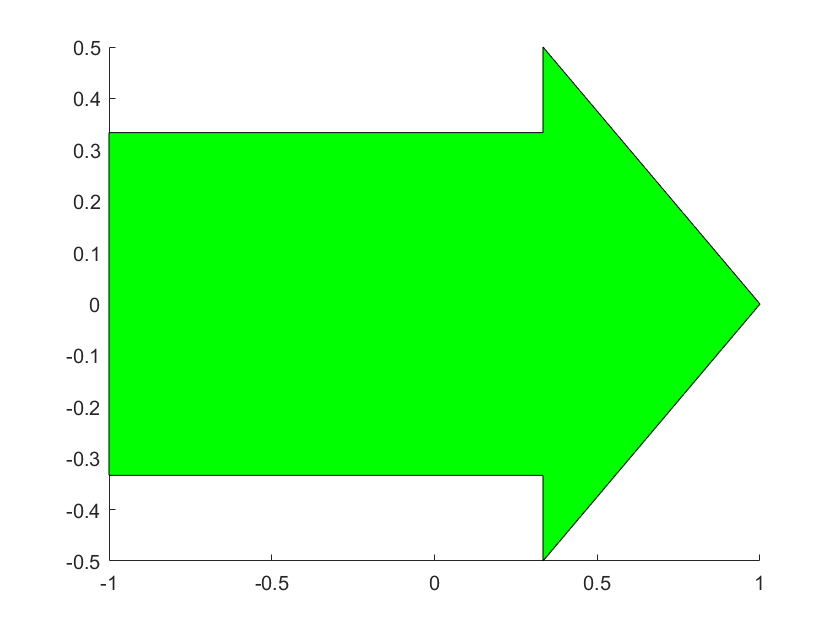

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in axis>isnumericAxes (line 513)
result = isnumeric(get(h,'XLim'));

Error in axis (line 176)
                if ~isnumericAxes(ax(j))

clear all; % LINE FOLLOWER
close all;

global err1;
global err2;
global out1;
global Ts;
global kpv;
global kiv;
global kdv;

x = [-1  , 1/3, 1/3, 1, 1/3, 1/3,-1  ];
y = [-1/3,-1/3,-1/2, 0, 1/2, 1/3, 1/3];
g = hgtransform;
patch('XData',x,'YData',y,'FaceColor','green','Parent',g)
colour = "green";


xlim([0 20])
ylim([0 20])
hold on;

line = linspace(0,20,100);
plot (linspace(0,20,100),line);

speed = 1/10;

r0 = pi/4;
const_err = pi/10000;
err1 = 0; 
err2 = 0;
out1 = 0;
kpv = 0.005;
kiv = 0.05;
kdv = 0.00001;
Ts = 1/500;

new_bearing = pi/9;
index=1;
switched=0;
for t=linspace(0,1,500)
  coords = [ g.Matrix(1,4)  g.Matrix(2,4)  0];
  %new_bearing = new_bearing;
  index=index+1;
  
  point_dist = point_to_line(coords,[0,0,0],[1,1,0]);
  if (coords(2)/coords(1)>1)
      point_dist = - point_dist;
  end
  dist(index) = point_dist;
  angles(index) = r0-new_bearing;
  if t>1/2 %PID toggle on
      if (switched)
        PID_change = PID_homemade(r0-new_bearing);
        new_bearing = new_bearing+PID_change;
        if (abs(angles(index))<0.1)
            switched = 0;
            err1 = 0; 
            err2 = 0;
            out1 = 0;
            kpv = 0.005;
            kiv = 0.05;
            kdv = 0.00001;
        end
      else
        PID_change = PID_homemade(dist(index));
        new_bearing = new_bearing+PID_change;
        if (abs(dist(index))<0.1)
            switched = 1;
            err1 = 0; 
            err2 = 0;
            out1 = 0;
            kpv = 0.1;
            kiv = 0.01;
            kdv = 0.0001;
        end
      end
      if (new_bearing > 5*r0/3)
            new_bearing = 5*r0/3;
      end
      if (switched)
        colour = "red";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      else
        colour = "yellow";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      end
  end
  
  delta = [speed*cos(new_bearing),speed*sin(new_bearing), 0];
  new_pos = coords + t*delta;

  

  g.Matrix = makehgtform('translate',new_pos,'zrotate', new_bearing);

  drawnow nocallbacks
end
hold off;
figure;
plot(dist);
xlabel("time")
ylabel("distance")
xlim([250,500]);
figure;
plot(angles);
xlabel("time")
ylabel("angle")
xlim([250,500]);

clear all; % SQRT FOLLOWER
close all;

global err1;
global err2;
global out1;
global Ts;
global kpv;
global kiv;
global kdv;

x = [-1  , 1/3, 1/3, 1, 1/3, 1/3,-1  ];
y = [-1/3,-1/3,-1/2, 0, 1/2, 1/3, 1/3];
g = hgtransform;
patch('XData',x,'YData',y,'FaceColor','green','Parent',g)
colour = "green";

axis equal
xlim([0 20])
ylim([0 20])
hold on;

line = linspace(0,20,100);
plot (linspace(0,20,100),2*sqrt(line));

speed = 1/10;

r0 = pi/4;
const_err = pi/10000;
err1 = 0; 
err2 = 0;
out1 = 0;
kpv = 0.5;
kiv = 0.05;
kdv = 0.00001;
Ts = 1/500;

new_bearing = pi/9;
index=1;
switched=0;
for t=linspace(0,1,500)
  coords = [ g.Matrix(1,4)  g.Matrix(2,4)  0];
  %new_bearing = new_bearing;
  index=index+1;
  

  curr_angle = atan(1/sqrt(coords(1))); %atan of derivative of function
  dx = 0.5;
  dy = dx * curr_angle;
  point_dist = point_to_line(coords,[coords(1),2*sqrt(coords(1)),0],[coords(1)+dx,2*sqrt(coords(1))+dy,0]);
  if (2*sqrt(coords(1))<coords(2))
      point_dist = - point_dist;
  end
  dist(index) = point_dist;
  angles(index) = curr_angle-new_bearing;
  if 1 %PID toggle on
      if (switched)
        PID_change = PID_homemade(angles(index));
        new_bearing = new_bearing+PID_change;
        if (abs(angles(index))<0.1)
            switched = 0;
            err1 = 0; 
            err2 = 0;
            out1 = 0;
            kpv = 0.005;
            kiv = 0.05;
            kdv = 0.00001;
        end
      else
        PID_change = PID_homemade(dist(index));
        new_bearing = new_bearing+PID_change;
        if (abs(dist(index))<0.1)
            switched = 1;
            err1 = 0; 
            err2 = 0;
            out1 = 0;
            kpv = 0.1;
            kiv = 0.01;
            kdv = 0.0001;
        end
      end
      if (new_bearing > 5*r0/3)
            new_bearing = 5*r0/3;
      end
      if (switched)
        colour = "red";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      else
        colour = "yellow";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      end
  end
  
  delta = [speed*cos(new_bearing),speed*sin(new_bearing), 0];
  new_pos = coords + t*delta;

  

  g.Matrix = makehgtform('translate',new_pos,'zrotate', new_bearing);
  drawnow nocallbacks
end
hold off;
figure;
plot(dist);
xlabel("time")
ylabel("distance")
xlim([250,500]);
figure;
plot(angles);
xlabel("time")
ylabel("angle")
xlim([250,500]);


clear all; % ARBITRARY PATH FOLLOWER
close all;
clc;

global err1;
global err2;
global out1;
global Ts;
global kpv;
global kiv;
global kdv;

offsetx = 6.2;
offsety = 61.3;
size = 6;
x = [-1  , 1/3, 1/3, 1, 1/3, 1/3,-1  ]*size;
y = [-1/3,-1/3,-1/2, 0, 1/2, 1/3, 1/3]*size;
g = hgtransform;
patch('XData',x,'YData',y,'FaceColor','green','Parent',g)
colour = "green";

axis equal
xlim([0 150])
ylim([0 100])
hold on;

% line_draw = linspace(0,20,100);
% plot (linspace(0,20,100),line_draw);
hold on;
colours = ["FF0000","00FF00","FFFF00","00FFFF","000006","000008","0000FF","000007","FF00FF"];

circle_coords = [25 25; 25 45; 5 20; 37.5 65; 100 65; 50 57.5; 57.5 57.5; 77.5 67.5; 50 25];
circle_coords(:,2) = abs(100-circle_coords(:,2))

circle_coords =    25.0000   75.0000
   25.0000   55.0000
    5.0000   80.0000
   37.5000   35.0000
  100.0000   35.0000
   50.0000   42.5000
   57.5000   42.5000
   77.5000   32.5000
   50.0000   75.0000


for i=1:length(colours)
    hold on;
    circleGen(circle_coords(i,1),circle_coords(i,2),2.5,(reshape(sscanf(colours(i).','%2x'),3,[]).'/255));
end
line_coords = [1262 412; 1137 712; 1087 762; 862 787; 287 762; 262 737; 137 537; 62 387 ];
line_coords = line_coords./10;
line_coords = flip(line_coords);
line_coords(:,2) = abs(100-line_coords(:,2))

line_coords =     6.2000   61.3000
   13.7000   46.3000
   26.2000   26.3000
   28.7000   23.8000
   86.2000   21.3000
  108.7000   23.8000
  113.7000   28.8000
  126.2000   58.8000


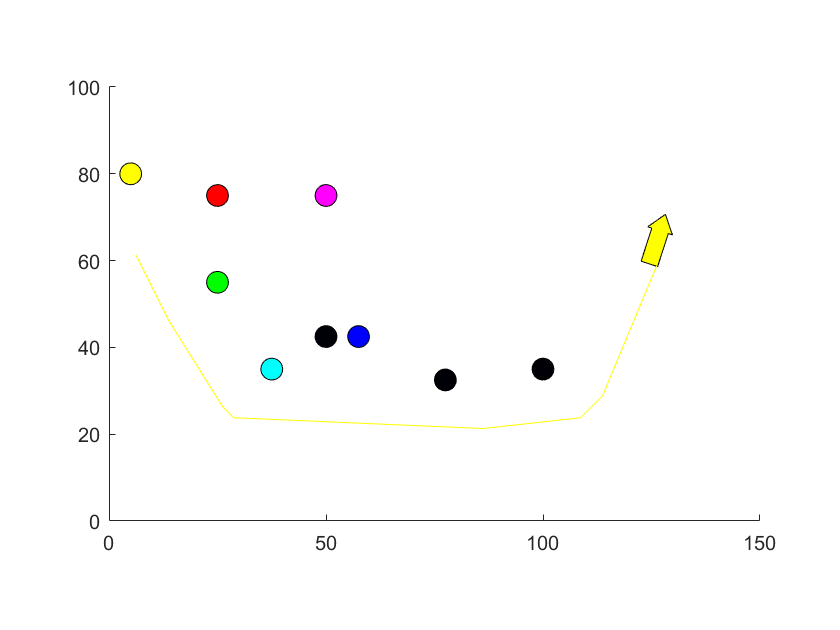

hold on;

for i=1:length(line_coords)-1
    line_angle(i) = ((line_coords(i,2)-line_coords(i+1,2))/((line_coords(i,1)-line_coords(i+1,1))));
    hold on;
    col ="red";
    line([line_coords(i,1) line_coords(i+1,1)],[line_coords(i,2) line_coords(i+1,2)],"color", col);
end



speed = 1;

err1 = 0; % ANGLE PID
err2 = 0;
out1 = 0;
kpv = 0.01;
kiv = 0;
kdv = 0.0001;
Ts = 1/500;

index = 1;
switched = 0;
active_line = 0;
new_bearing = 0;
g.Matrix(1,4)=g.Matrix(1,4);
g.Matrix(2,4)=g.Matrix(2,4)+offsety;
for t=linspace(0,1,500)
  coords = [ g.Matrix(1,4)  g.Matrix(2,4)  0];
  index=index+1;
  
  if (coords(1)>line_coords(active_line+1,1))
      active_line = active_line + 1;
      if (active_line > length(line_angle))
          break;
      end
      line([line_coords(active_line,1) line_coords(active_line+1,1)],[line_coords(active_line,2) line_coords(active_line+1,2)],"color", "yellow");
  end
  if (active_line>0)
      curr_angle = atan(line_angle(active_line));
      point_dist = point_to_line(coords,[line_coords(active_line,1),line_coords(active_line,2),0],[line_coords(active_line+1,1),line_coords(active_line+1,2),0]); % THIS
      
      x1 = line_coords(active_line+1,1);
      y1 = line_coords(active_line+1,2);
      if (coords(2)>(line_angle(active_line)*(coords(1)-x1)+y1))
          point_dist = - point_dist; % ALSO THIS
      end
      dist(index) = point_dist;
      angles(index) = curr_angle-new_bearing;
  else
      dist(index)=0;
      angles(index)=0;
  end
  if 1 %PID toggle on
      if (~switched)
        PID_change = PID_homemade(angles(index));
        new_bearing = new_bearing+PID_change;
        if (abs(angles(index))<0.01 && active_line > 0)
            switched = 1; % DISTANCE PID VALUES
            err1 = 0; 
            err2 = 0;
            out1 = 0;
            kpv = 0.01;
            kiv = 0.0;
            kdv = 0.00001;
        end
      else
        PID_change = PID_homemade(dist(index));
        if PID_change > 0.05
            PID_change = 0.05;
        elseif PID_change < -0.05
            PID_change = -0.05;
        end
        new_bearing = new_bearing+PID_change;
        if (abs(dist(index))<0.08 && active_line > 0)
            switched = 0;
            err1 = 0; % ANGLE PID
            err2 = 0;
            out1 = 0;
            kpv = 0.1;
            kiv = 0;
            kdv = 0.0001;
        end
      end
      if (switched)
        colour = "red";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      else
        colour = "yellow";
        patch('XData',x,'YData',y,'FaceColor',colour,'Parent',g)
      end
  end
  
  delta = [speed*cos(new_bearing),speed*sin(new_bearing), 0];
  new_pos = coords + t*delta;

  

  g.Matrix = makehgtform('translate',new_pos,'zrotate', new_bearing);

  drawnow nocallbacks
end
hold off;

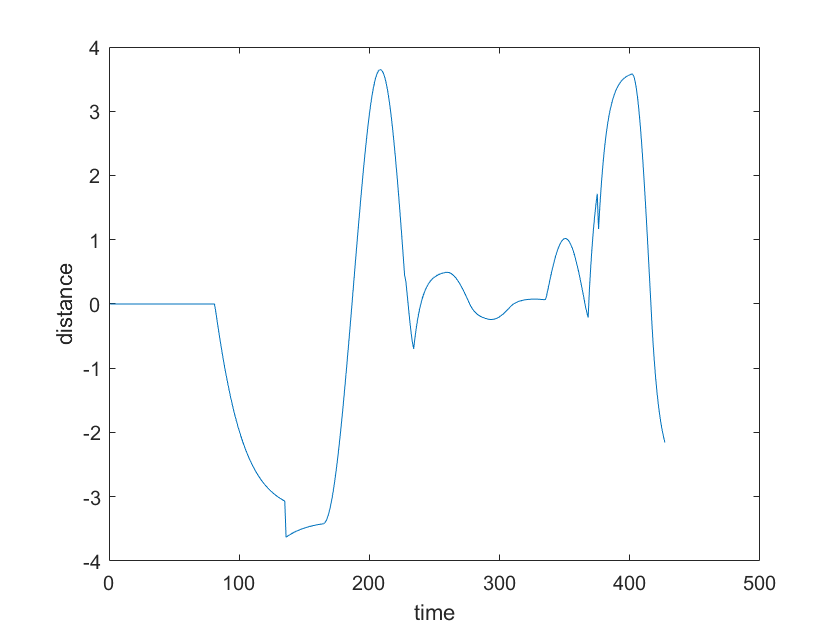

figure;
plot(dist);
xlabel("time")
ylabel("distance")
xlim([0,500]);

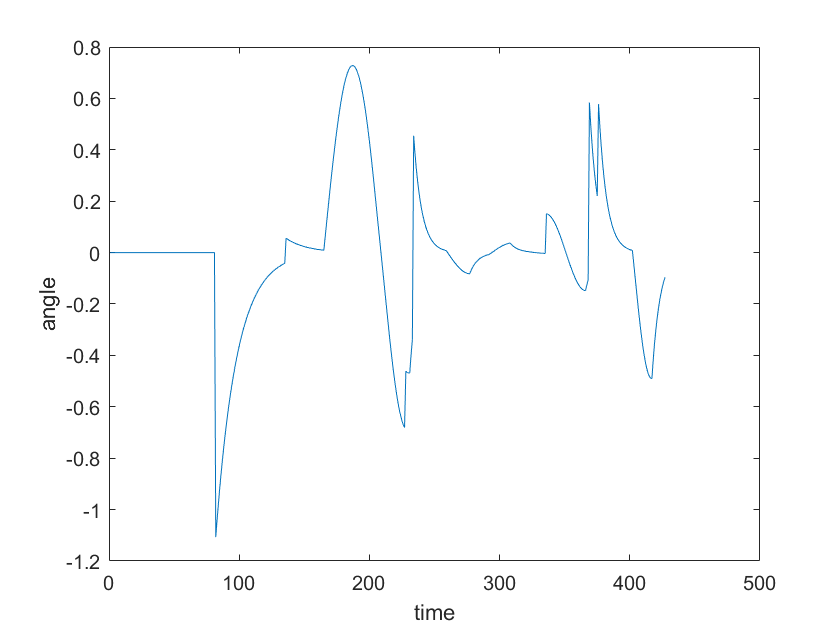

figure;
plot(angles);
xlabel("time")
ylabel("angle")
xlim([0,500]);